## Read the Spine Image

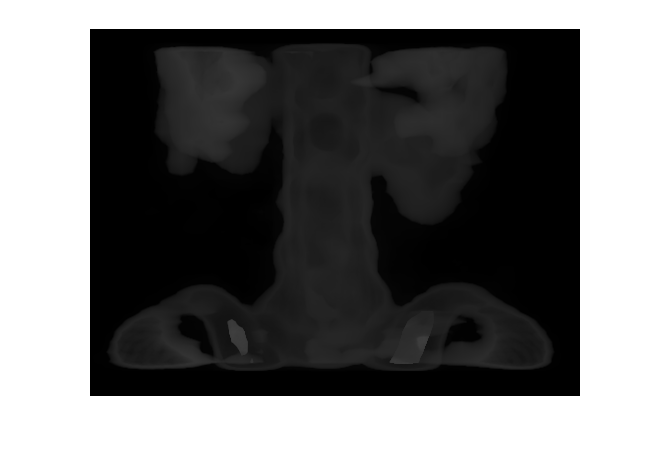

img = imread("spine.tif");
imshow(img)

## Open it with Image Viewer App

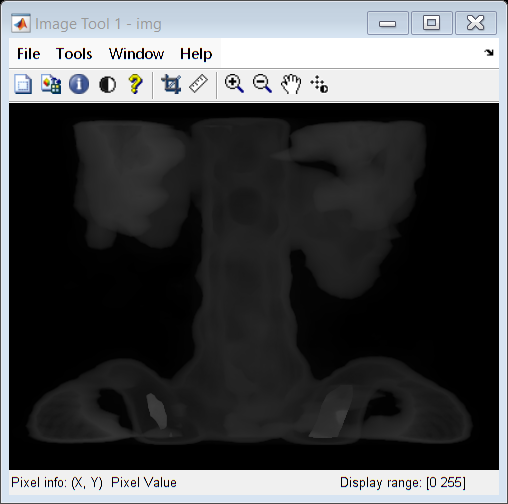

imtool(img)

## Show the Histogram of Spine Image

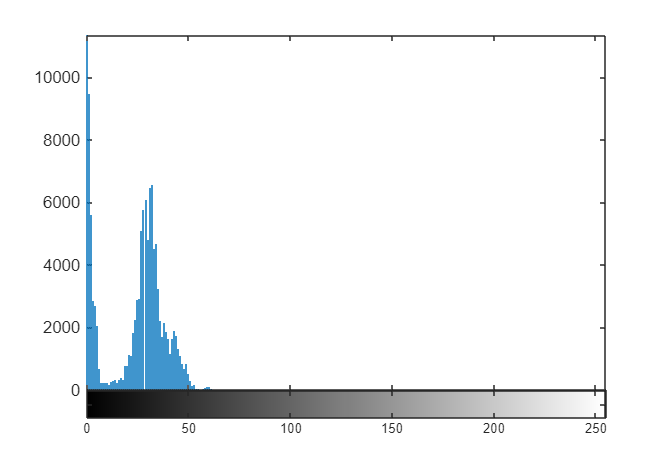

imhist(img)

## Adjust the Spine Image Histogram

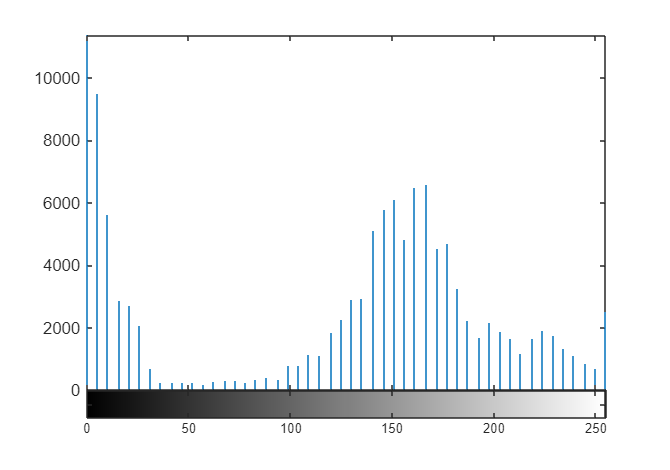

imAdj = imadjust(img);
imhist(imAdj)

- imadjust() does the same thing as "Eliminate Outliers" option on Image Viewer App's Adjust Contrast tool.

- Eliminate Outliers stretches the values a little more ensuring that at least one percent of the pixels have the maximum brightness value and one percent have the minimum, this prevents a single exceptionally bright or dark pixel from overly influencing the scaling.

## Compare the Original Image and Adjusted Image

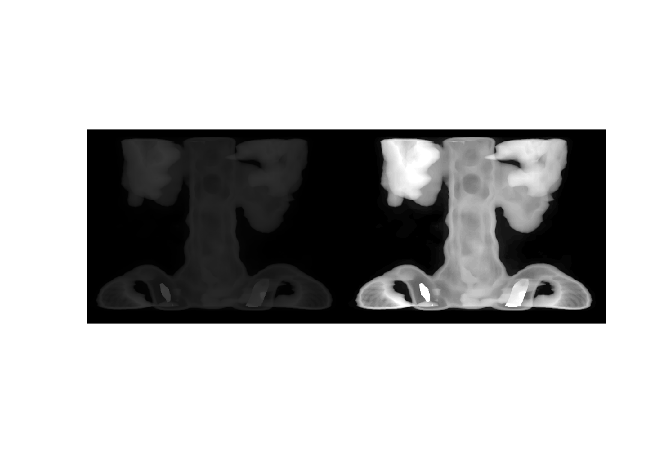

montage({img, imAdj})

## Specify Portion of the Image to Focus On

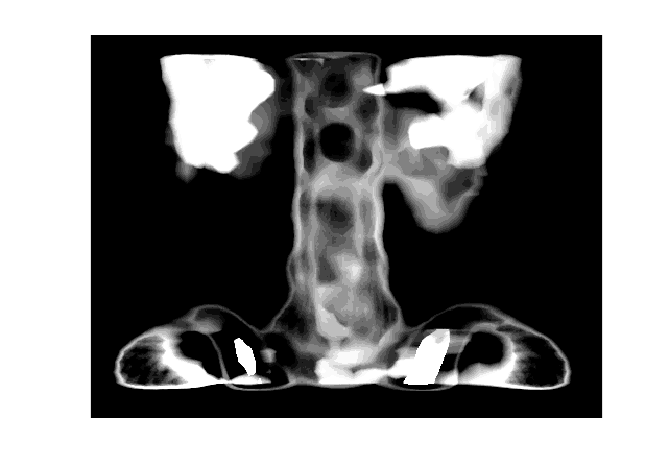

imAdj2 = imadjust(img, [0.1,0.15], [0,1]);
imshow(imAdj2)

- Keep only the pixel with intensities between 25 and 40 in the original image. 

- This corresponds to 10 and 15 percent of the total available intensity. (0.10 to 0.15)

- We will scale the intensity values to use the entire range from zero to 100 percent (0,1)

- Values below 25 are set to **zero**, values above 40 become **255**.

## Read Tire Image and Adjust It

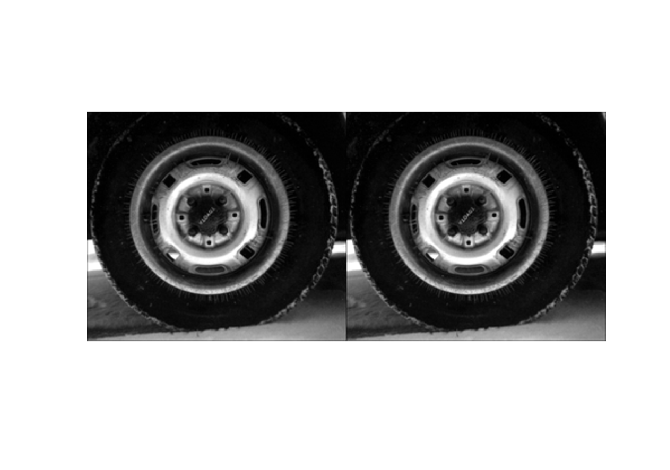

imgTire = imread("tire.tif");
imAdjTire = imadjust(imgTire);
montage({imgTire, imAdjTire})

- The tire image is very dark. Adjusting contrast is not change anything alone.

## Histogram of Tire Image

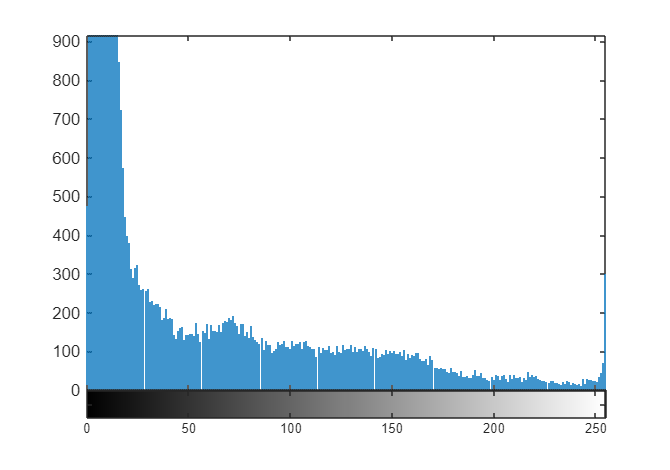

imhist(imgTire)

## Equalize the Histogram

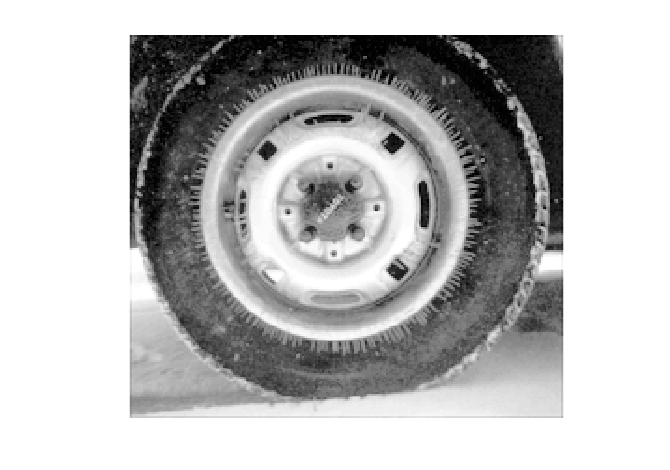

imgEq = histeq(imgTire);
imshow(imgEq)

- histeq() function attemps to spread the pixel intensities out to use all the available intensities roughly equally.

## Compare Original Tire Image and Equal Histogram Tire Image

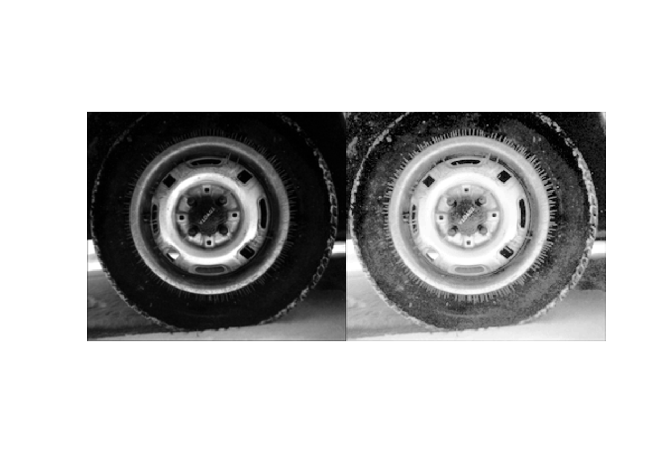

montage({imgTire, imgEq})

## Adaptive Histogram Equalization

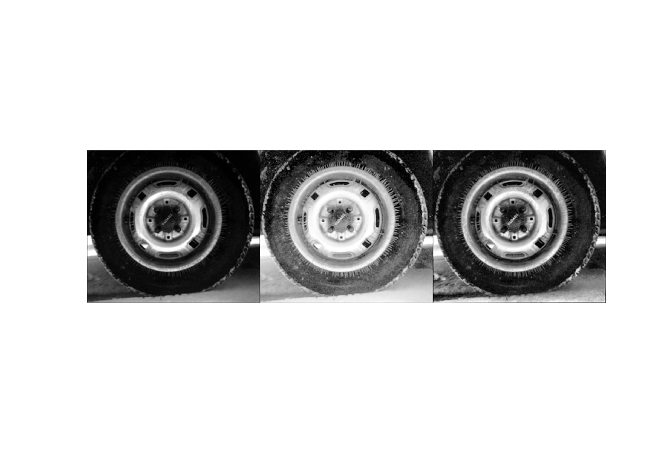

imgAdaptive = adapthisteq(imgTire);
montage([imgTire,imgEq, imgAdaptive])

- With **histeq()** function equalize the histogram of entire image

- **adapthisteq()** function is breaks it into tiles and each tile is equalized seperately then they are blended together for a final image

## Reading a Crack Image for Reference

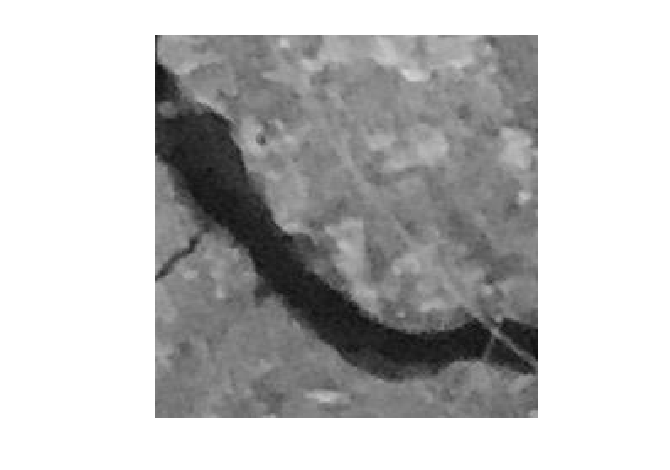

imgCrackRef = imread("00155.jpg");
imgCrackRef = im2gray(imgCrackRef);
imshow(imgCrackRef)

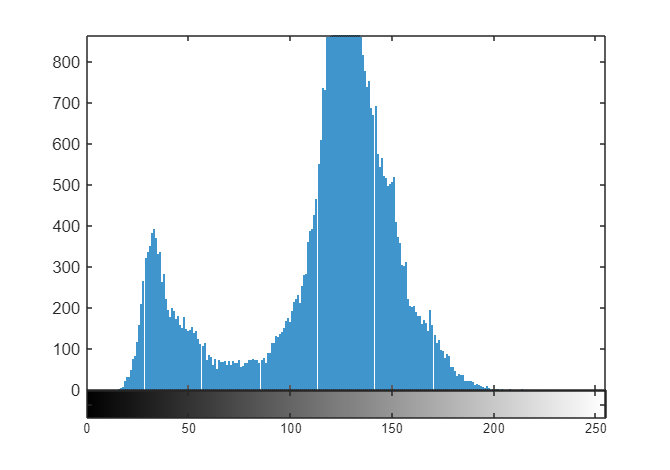

imhist(imgCrackRef)

- This image is a reference because it has two well-defined peaks, making the threshold value clear.

## Reading the Crack Image

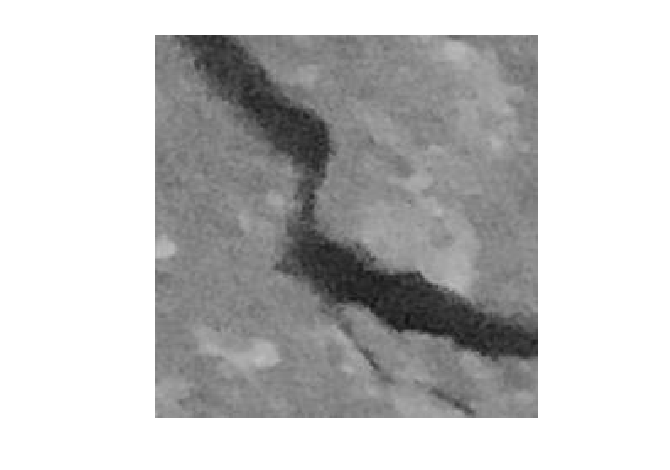

imgCrack = imread("00175.jpg");
imgCrack = im2gray(imgCrack);
imshow(imgCrack)

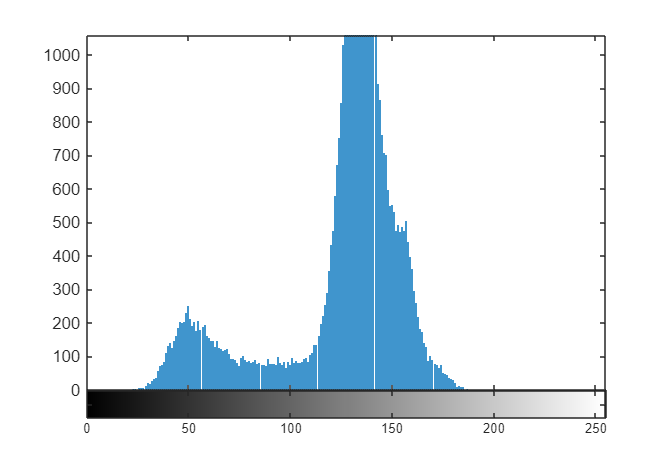

imhist(imgCrack)

- This image does not have two well-defined peaks. The crack is less sharp than reference image. So, we will need to use the reference image to adjust it.

## Histogram Match with Crack Reference Image and the Crack Image

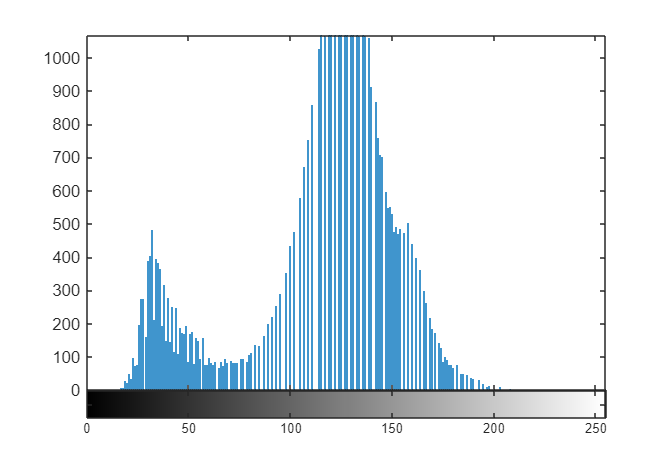

imgMatch = imhistmatch(imgCrack, imgCrackRef, 256);
imhist(imgMatch)

- **imhistmatch() **function matches the histogram of the image to that of a reference image.

## Compare the Original Crack Image and Histogram Matched Crack Image

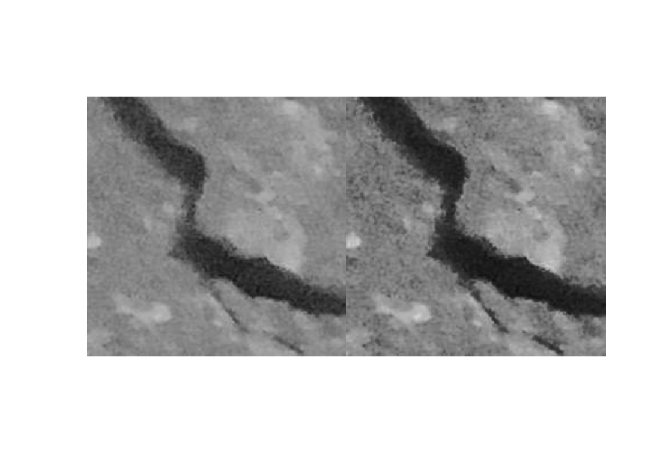

montage({imgCrack, imgMatch})